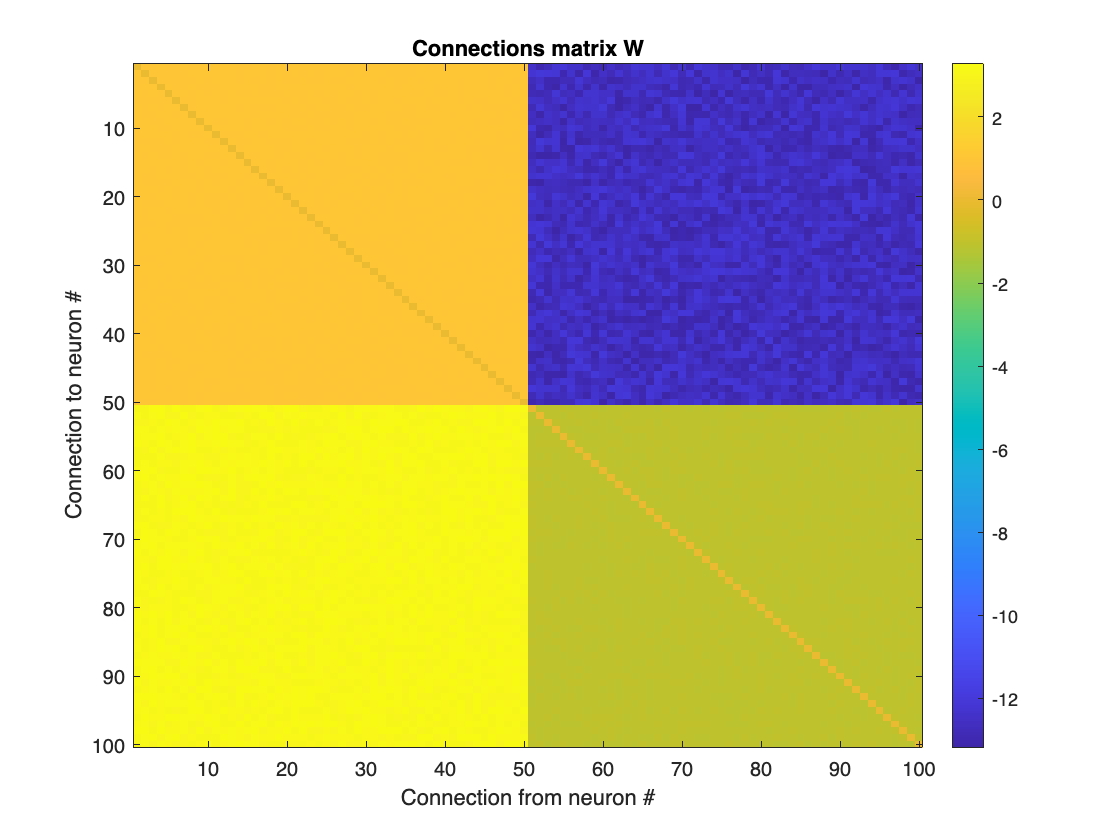

clear; clf; clf;
tic;

% Number of neurons in the simulation
NE = 50;       %Excitatory
NI = 50;       %Inibhitory
numNeurons = NE+NI; %Total population

% Connection strength 
wEE = 1;       %Strength of self-excitatory feedback
wEI = -12;       %Strength of connections between E–I
wIE = 3;       %Strength of connections between I-E
wII = -1;        %Strength of self-inhibitory feedback

% External input
I_ext_E = 2;
I_ext_I = 7;


%Simulation parameters
T = 1000;               %Simulation duration in ms
dt = .1;              %Time step

range_t = 0:dt:T;       %Initializing time axis
N = length(range_t);   

I_ext_I = I_ext_I * (1+0.5*(rand(NE, N)-.5));
I_ext_E = I_ext_E * (1+0.5*(rand(NI, N)-.5));
%Creting connectivity matrix
W = zeros(numNeurons);
W(1:NE,1:NE) = wEE;
W(1:NE,1+NE:end) = wEI;
W(1+NE:end,1:NE) = wIE;
W(1+NE:end,1+NE:end) = wII;
W = W.*(1+.1*rand(size(W)));
W(eye(length(W))==1)=0;


%Plot connectivity matrix 

imagesc(W)
colorbar
title('Connections matrix W')
xlabel('Connection from neuron #')
ylabel('Connection to neuron #')

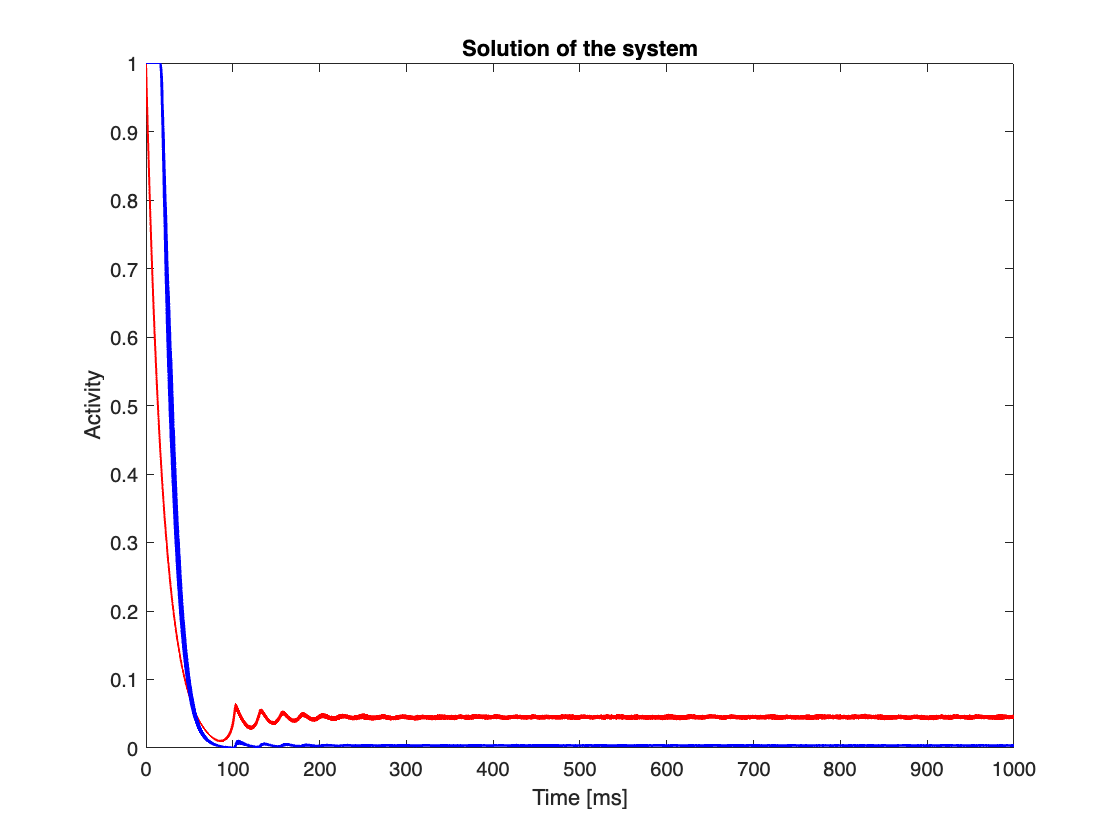



%Simulate the Wilson-Cowan equations

r = simulate_WC(W, T, dt, I_ext_E, I_ext_I, NE, NI);

rE = r(1:NE,:);
rI = r(1+NE:end,:);

plot(0:dt:T, rE, 'LineWidth', 1, 'Color', 'red' )
hold on 
plot(0:dt:T, rI, 'LineWidth', 1, 'Color', 'blue')

ylabel('Activity')
xlabel('Time [ms]')
title('Solution of the system')
ylim([0 1])

hold off

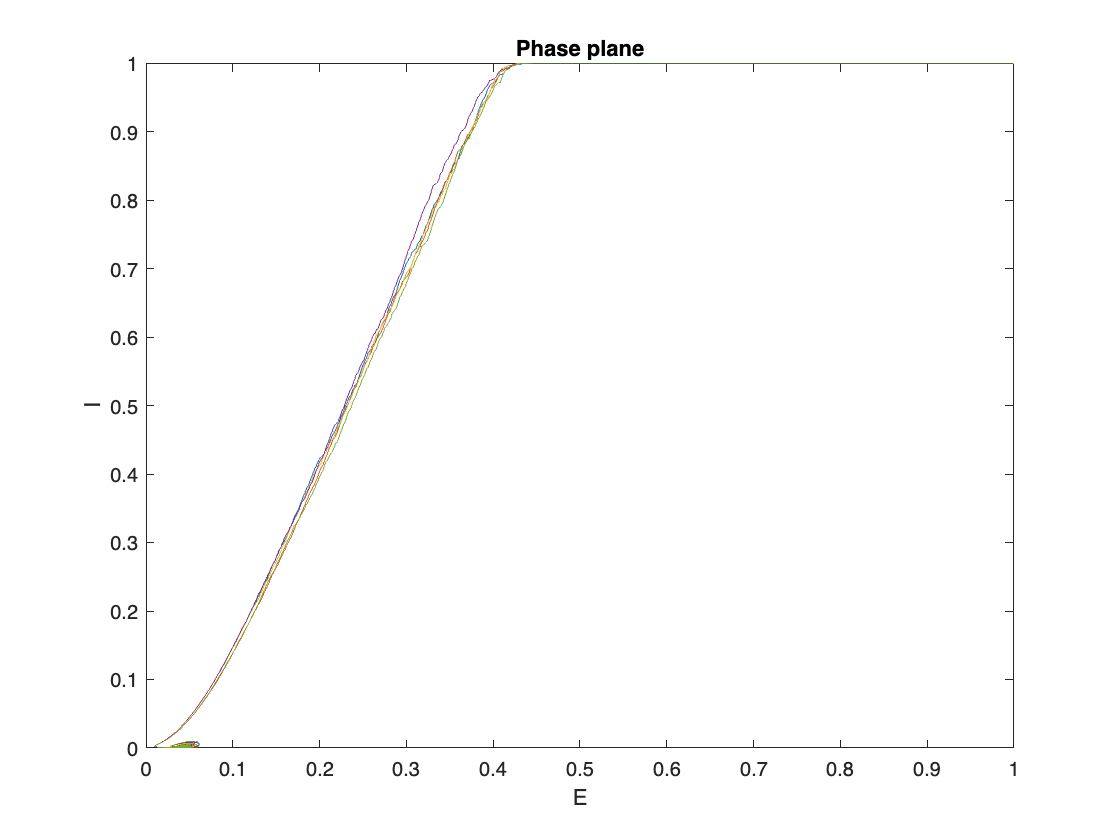



%Phase plane analysis
for i=1:5      %Plot the first 30 trajectories
    plot(rE(i, :), rI(i, :), 'LineWidth', 0.1)
    hold on
end
hold off
xlabel('E')
ylabel('I')
title('Phase plane')

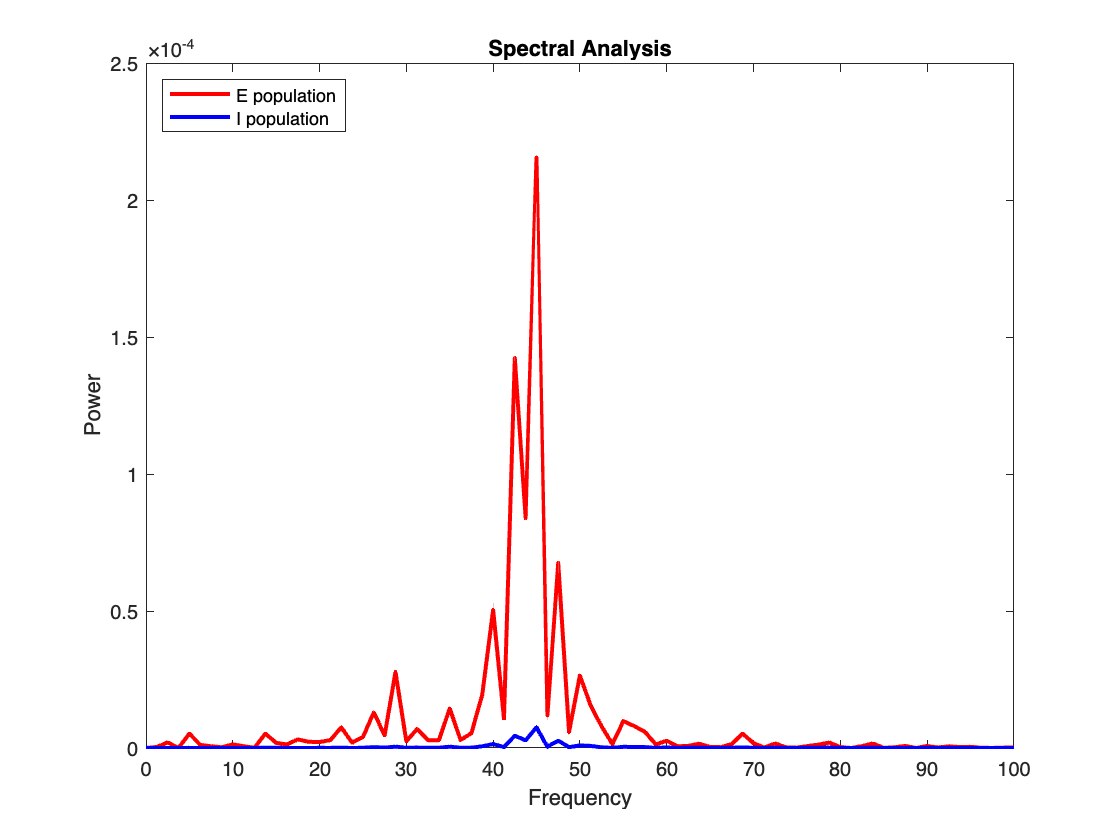

mean_rE = mean(rE, 1);
mean_rI = mean(rI, 1);

t_trans = 200;
id_trans = t_trans/dt;

X = mean_rE(id_trans:end);
Y = mean_rI(id_trans:end);

X = X - nanmean(X);
Y = Y - nanmean(Y);

% Compute the Fast Fourier Transform (FFT) of rE and rI
FFT_rE = fft(X);
FFT_rI = fft(Y);

N = length(FFT_rE);

% Set parameters for the Spectral Analysis
fs = 1/(dt*1e-3);       % sampling frequency
f = (0:N-1)*(fs/N);     % frequency range
power_rE = abs(FFT_rE).^2/N;    % power of the DFT for E population
power_rI = abs(FFT_rI).^2/N;

plot(f, power_rE, 'LineWidth', 2, 'Color', 'r')
hold on
plot(f, power_rI, 'LineWidth', 2, 'Color', 'b')
xlabel('Frequency')
ylabel('Power')
xlim([0 100])
legend('E population', 'I population', Location='northwest')
title('Spectral Analysis')
hold off

elapsedTime = toc; % End timing and get elapsed time in seconds

% Convert the time to minutes and seconds
minutes = floor(elapsedTime / 60);
seconds = rem(elapsedTime, 60);

% Display the message
fprintf('Elapsed time: %d minutes and %.2f seconds\n', minutes, seconds);

Elapsed time: 0 minutes and 5.11 seconds


function f = F(x, a, theta)
    f = (1 + exp(-a * (x - theta))).^-1 - (1 + exp(a * theta)).^-1;
end



function [r] = simulate_WC(W, T, dt, I_ext_E, I_ext_I, NE, NI)

    % Excitatory parameters
    tau_E = 20;     %Timescale of the E population [ms]
    a_E = 1;        %Gain of the E population
    theta_E = 5;    %Threshold of the E population
    
    % Inhibitory parameters
    tau_I = 10;     %Timescale of the I population [ms]
    a_I = 1;        %Gain of the I population
    theta_I = 20;   %Threshold of the E population
    
    numNeurons = length(W);
    
    range_t = 0:dt:T;       %Time axis
    N = length(range_t);
    
    r = ones(numNeurons, N);
    
    for i=1:N-1 
        
        dr_E = dt/tau_E*(-r(1:NE, i) + F(W(1:NE, :)*r(:, i) + I_ext_E(:, i), a_E, theta_E));
        dr_I = dt/tau_I*(-r(1+NE:end, i) + F(W(1+NE:end,:)*r(:, i) + I_ext_I(:, i), a_I, theta_I));
    
        r(1:NE,i+1) = r(1:NE,i) + dr_E;
        r(1+NE:end,i+1) = r(1+NE:end,i) + dr_I;
    end

end